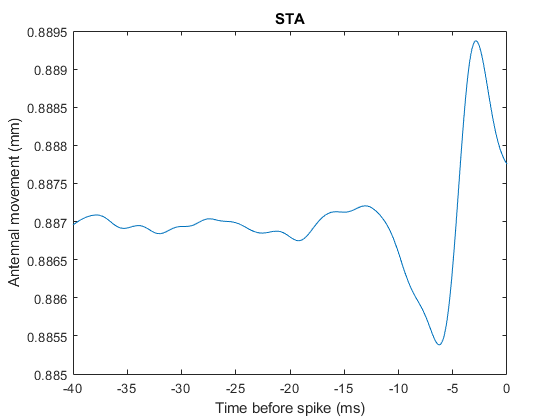

raster_data_1 = P(1).raster(:,start_stim:stop_stim);
raster_data_2 = P(2).raster(:,start_stim:stop_stim);
wn_1 = P(1).antennal_movement(:,start_stim:stop_stim);
wn_2 = P(2).antennal_movement(:,start_stim:stop_stim);

window = 0.04;
fs = parameters.fs;

[m,~] = size(raster_data_1);

all_spike_triggers = [];
for i=1:m
    spike_locs = find(raster_data_1(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-window*fs)>= 0
            
            spike_triggers = wn_1(1,(spike_locs(j)-window*fs):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
            all_spike_triggers = [all_spike_triggers; spike_triggers];
        end
    end

end

STA = mean(all_spike_triggers,1);
t= linspace(-window*1e3,0,length(STA));

plot(t,STA);
title("STA");
xlabel("Time before spike (ms)");
ylabel("Antennal movement (mm)");

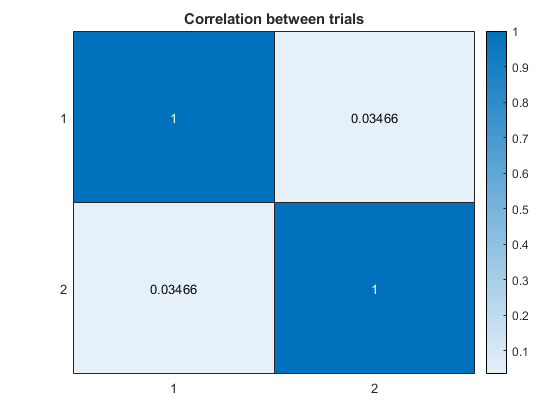



corr_coef_1 = corrcoef(raster_data_1(1,:), raster_data_1(2,:));
heatmap(corr_coef_1);
title('Correlation between trials');

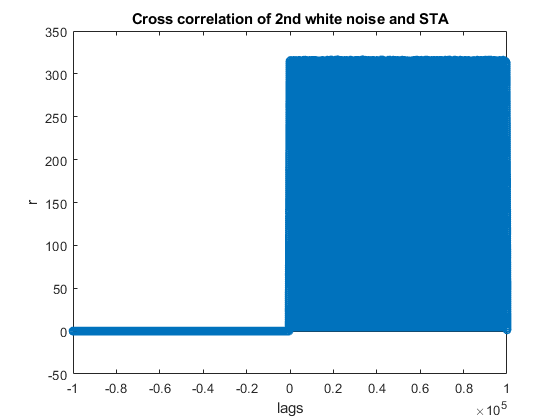


[r,lags]  = xcorr(wn_2(1,:),STA);
stem(lags,r);
title("Cross correlation of 2nd white noise and STA");
ylabel("r");
xlabel("lags");

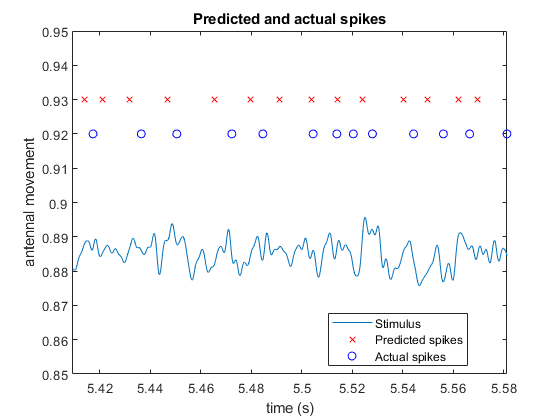


wn_1_spike_locs = find(raster_data_1(1,:)==1);
isi = diff(wn_1_spike_locs);
predicted_spikes = nan(1,10*fs+1);

[~,spike_locs] = findpeaks(r,"MinPeakDistance",min(isi), "MinPeakHeight", corr_coef_1(1,2));
spike_locs_ = find(spike_locs>1e5);
predicted_spikes(spike_locs(spike_locs_)-1e5) = 0.93;
% predicted_spikes(spike_locs) = 0.93;
spike_locs_2 = nan(1,10*fs+1);
t = linspace(0,10,length(wn_2));
spike_locs_2_ind = find(raster_data_2(1,:)==1);
spike_locs_2(spike_locs_2_ind)=0.92;
plot(t, wn_2(1,:), t, predicted_spikes, 'rx', t, spike_locs_2, 'bo');
ylabel('antennal movement');
xlabel('time (s)');
title("Predicted and actual spikes");
legend("Stimulus", "Predicted spikes", "Actual spikes", "Location","best");
ylim ([0.85 0.95]);

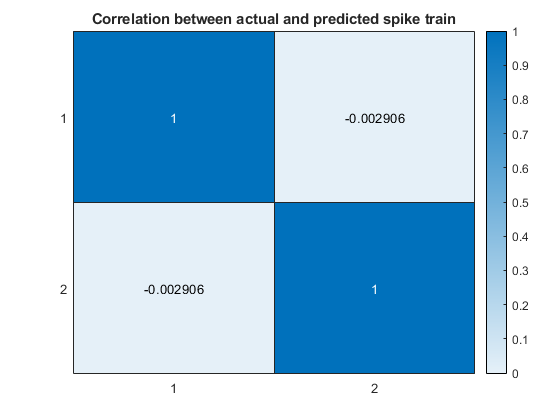


ind = isnan(predicted_spikes);
predicted_spikes(ind) = 0;
corr_coef_prediction = corrcoef(predicted_spikes, raster_data_2(1,:));
heatmap(corr_coef_prediction)
title('Correlation between actual and predicted spike train')

% w = conv(wn_2(1,:),STA);
% plot(w);

% wn_2_filt = filter(STA,1,wn_2(1,:));
% plot(wn_2_filt)
